clear all
clc;

## Radar Specifications

@auther Pravin

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

max_range = 200 ; % Max Range = 200m
delta_range = 1 ; % Range Resolution = 1 m
max_velocity = 100 ;  % Max Velocity = 100 m/s
speed_of_light =  3e8 ; %speed of light = 3e8

## User Defined Range and Velocity of target

define the targets initial position and velocity. Note : Velocity remains contant

start_range = 110  ; % Target Initial Range
velocity = 40 ;   % Target Velocity

## FMCW Waveform Generation

%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
B      = speed_of_light / (2 * delta_range)            % Calculate the Bandwidth (B)

B = 150000000

Tchirp = 5.5 * (  max_range * 2 / speed_of_light)              % Chirp Time (Tchirp)

Tchirp = 7.3333e-06

slope  = B / Tchirp                                     % Slope of the FMCW

slope = 2.0455e+13



%Operating carrier frequency of Radar
fc = 77e9 ;  % Carrier frequency, Hz

%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation.
Nd=128;                       % #of doppler cells OR #of sent periods % number of chirps


%The number of samples on each chirp.
Nr=1024;                      %for length of time OR # of range cells


% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t));        %transmitted signal
Rx=zeros(1,length(t));        %received signal
Mix = zeros(1,length(t));     %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

## Signal generation and Moving Target simulation

% Running the radar scenario over the time.
for i=1:length(t)
    %For each time stamp update the Range of the Target for constant velocity.
    r_t(i) =  velocity * t(i)  + start_range;
    td(i) = (2*r_t(i)) / speed_of_light;

    %For each time sample we need update the transmitted and
    %received signal.
    Tx(i) = cos(2*pi*(fc*t(i) + (slope*t(i)^2)/2));
    Rx(i) = cos(2*pi*(fc*(t(i) - td(i)) + (slope*(t(i) - td(i))^2)/2));
end
%Now by mixing the Transmit and Receive generate the beat signal
%This is done by element wise matrix multiplication of Transmit and
%Receiver Signal
Mix = Tx.*Rx;

## RANGE MEASUREMENT

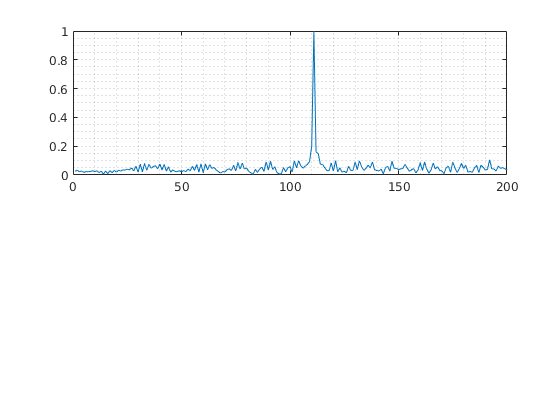

%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix2=reshape(Mix,[Nr,Nd]);

%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
full_fft = fft(Mix2, Nr);          % run the FFT

% Take the absolute value of FFT output
fft_abs = abs(full_fft) ;           % absolute
fft_abs = fft_abs./max(fft_abs);    % Normalize

% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
half_fft = fft_abs(1:Nr/2-1);         % half of the FFT

%plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

% plot FFT output
plot (half_fft);  grid minor
axis ([0 200 0 1]);

## RANGE DOPPLER RESPONSE

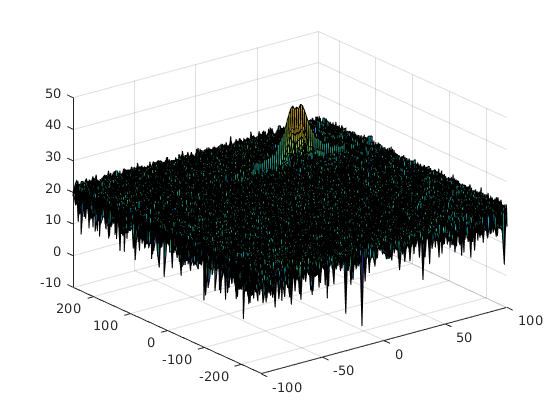

% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);


% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## CFAR implementation

%Slide Window through the complete Range Doppler Map
%Select the number of Training Cells in both the dimensions.
Tr = 16;
Td = 12;

%Select the number of Guard Cells in both dimensions around the Cell under
%test (CUT) for accurate estimation
Gr = 8;
Gd = 6;

% offset the threshold by SNR value in dB
offset=7;

%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);
c_range_cells = Tr + Gr

c_range_cells = 24

c_doppler_cells = Td + Gd

c_doppler_cells = 18

start_range = c_range_cells + 1                % Tr + Gr + 1

start_range = 25

end_range =  Nr/2 - c_range_cells              % Nr/2 - Tr - Gr

end_range = 488

start_doppler = c_doppler_cells + 1              % Td + Gd + 1

start_doppler = 19

end_doppler =  Nd - c_doppler_cells              % Nd - Td - Gd

end_doppler = 110

windw_norm = (2*c_doppler_cells + 1)* (2*c_range_cells + 1) -(Gr*Gd)-1

windw_norm = 1764

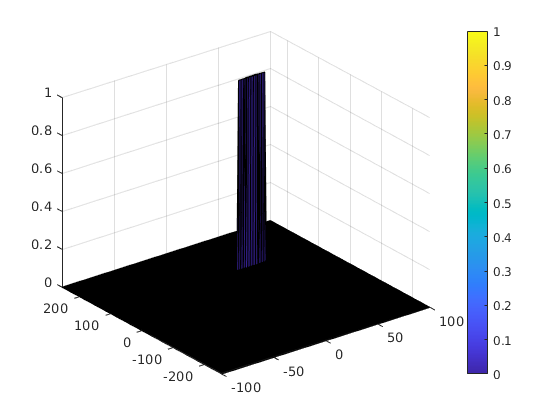


% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.

CFAR = zeros(size(RDM)); % set all to zero
for range_index = start_range : end_range
    for doppler_index = start_doppler : end_doppler
        %slide and db2pow (conv)
        training_cells = db2pow(RDM(range_index - c_range_cells : range_index + c_range_cells, ...
                                    doppler_index - c_doppler_cells : doppler_index + c_doppler_cells));
        % sum , normalize  and do pow2db
        training = pow2db(sum(sum(training_cells)) / windw_norm);
        % add the offset
        threshold = training + offset;

        CUT = RDM(range_index,doppler_index);
        if (CUT > threshold)  % set to 1
            CFAR(range_index,doppler_index) = 1;
        end
    end
end


%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.

figure,surf(doppler_axis,range_axis,CFAR);

colorbar;